# Advanced Example

This example shows basic use of the Classes

addpath("Classes\","Classes\Models\","Data\")

## Example Dataset

The Dataset from Luis Candanedo, luismiguel.candanedoibarra '@' umons.ac.be, University of Mons (UMONS). 

***Data Set Information:***

*The data set is at 10 min for about 4.5 months. The  house temperature and humidity conditions were monitored with a ZigBee  wireless sensor network. Each wireless node transmitted the temperature  and humidity conditions around 3.3 min. Then, the wireless data was  averaged for 10 minutes periods. The energy data was logged every 10  minutes with m-bus energy meters. Weather from the nearest airport  weather station (Chievres Airport, Belgium) was downloaded from a public data set from Reliable Prognosis (rp5.ru), and merged together with the experimental data sets using the date and time column. Two random  variables have been included in the data set for testing the regression  models and to filter out non predictive attributes (parameters).*

Cited from from [https://archive.ics.uci.edu/ml/datasets/Appliances+energy+prediction#](https://archive.ics.uci.edu/ml/datasets/Appliances+energy+prediction#)

load("energydatacomplete.mat")
data_training=energydatacomplete(1:6*24*7,:);
disp(head(energydatacomplete,4))

           Date            TimeOfDay    Appliances    Lights     T1       RH_1      T2      RH_2      T3       RH_3       T4       RH_4       T5      RH_5       T6       RH_6       T7       RH_7      T8      RH_8       T9      RH_9     T_out     Press_mm_hg    RH_out    Windspeed    Visibility    Tdewpoint     rv1       rv2  
    ___________________    _________    __________    ______    _____    

## Ensambles of Models and Training Options

You can mix and match diffrent models for diffrent autoregressive Variables.

First we create a Neural Network to predict all tempratures based on the previous and on the Appliance energy consumption, as well as the outside tempratue

%Create an AutoRegressor Object
Ensamble=AutoRegressor();

%Define and add a Model to the Ensamble
Md_T.Features=["T_out","Appliances","Lights","T"+(1:9)];
Md_T.Targets="Next_T"+(1:9);
Md_T.LayerSize=[10];
Md_T.Model=MLP(Md_T.Features,Md_T.Targets,Md_T.LayerSize);
Ensamble = Ensamble.addModel(Md_T.Model);

We can assume T_out to be known, as it can be derived from the local weather forecast.

But we base our prediction of on the Appliances and Ligths. So we need a model to also predict those in an auto regressive manner. Lets create an Gaussian Process for that purpose.

We specifity the targets as follows:

Md_T2.Targets=["Next_Appliances","Next_Lights"];

As Features we use the values of the targets from the previous timestep.

Md_T2.Features=["Appliances","Lights"];

We also want to use the tempratures as Features, but instead of using the values of the previous timestemp, we can use the predictions of the Neural Network.

Md_T2.Features=[Md_T2.Features,"TimeOfDay","Next_T"+(1:9)];

You can specifiy Training Options by creating a struct, where the field names and values are valid name value paris for the fitrsvm function.

Md_T2.TrainOpt.Kernelfunction='ARDExponential';
Md_T2.TrainOpt.Standardize=true;
Md_T2.TrainOpt.ActiveSetMethod='entropy';
Md_T2.TrainOpt.ActiveSetSize=143;

Md_T2.Model=GP(Md_T2.Features,Md_T2.Targets,Md_T2.TrainOpt);
Ensamble = Ensamble.addModel(Md_T2.Model);

## Benchmarking

You can benchmark your system, by repeativly makeing autoregressive Predictions an observe the behaviour as in an production enviorment

testing_options=struct(...
    'InitialTrainingSamples',24*6,...
    'ClosedLoopTimeHorizion',24*6,...
    'UseParallel',0,...
    'verbose',1,...
    'Timesteps_skipped',0,...
    'RetrainFrequency',6*24);%train once a day
Bench= AutoRegressionBenchmark(data_training,Ensamble,testing_options);
Bench=Bench.benchmark;

Progress 0% 
Progress 10% 
Progress 20% 
Progress 30% 
Progress 40% 


Progress 50% 
Progress 60% 


Progress 70% 
Progress 80% 


Progress 90% 
Progress 100% 


To quickly visualise the benchmark Results you can use the dispResults function

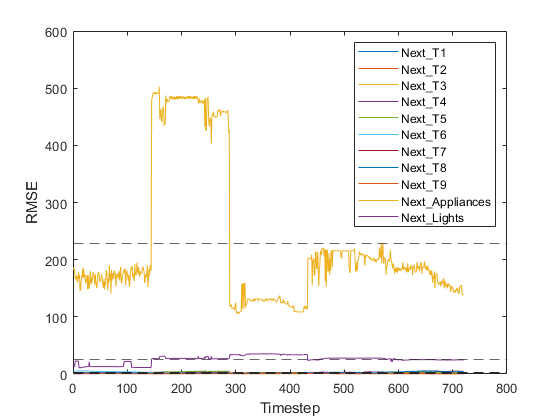

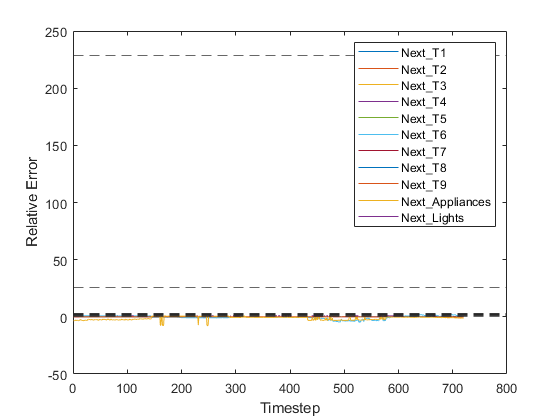

Bench.dispResults

For a more analysis statistics can be derived from the Data in the ErrorLog property of the benchmark object

disp(head(Bench.ErrorLog))

    Timestep           Date              GroundTruth        Predictions         Error         ErrorRelative      ErrorDynamic          RMSE             dtw3        UserData
    ________    ___________________    _______________    _______________    ____________    _______________    _______________    _____________    ____________    ________

      145       2016-01-12 17:00:00    [144×11 double]    [144×11 double]    [1x11 table]    [144×11 double]    [144×11 double]    [1×11 double]    [2.5793e+03]    []    []
      146       2016-01-12 17:10:00    [144×11 double]    [144×11 double]    [1x11 table]    [144×11 double]    [144×11 double]    [1×11 dou